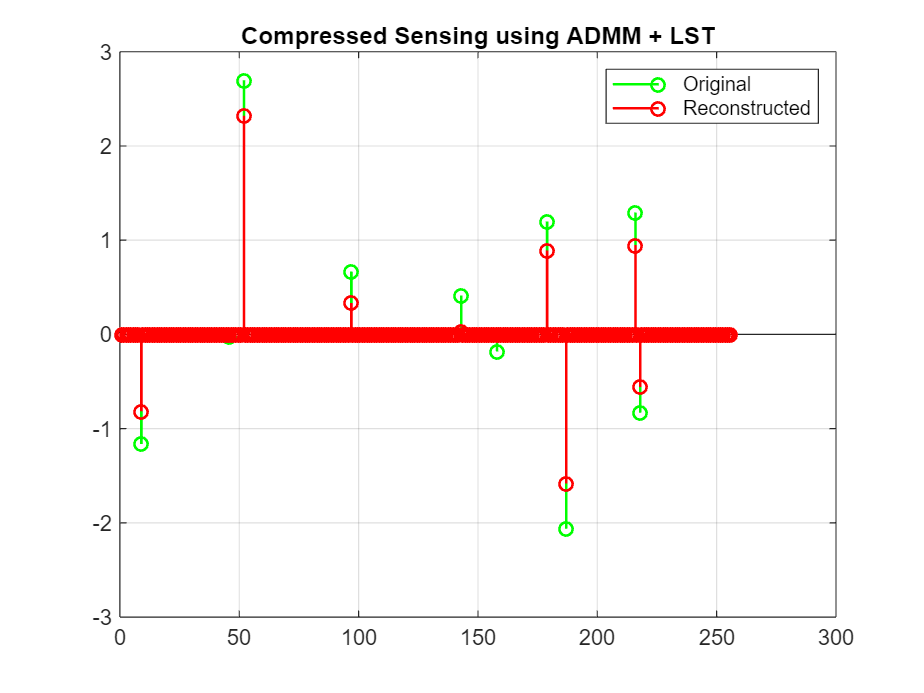

clc; clear; close all;

% Parameters
n = 256;
m = 120;
s = 10;
rho = 1;
lambda = 0.05;
maxIter = 200;

% Sensing matrix (NORMALIZED)
A = randn(m,n);
A = A ./ vecnorm(A);

% Sparse signal
x_true = zeros(n,1);
idx = randperm(n,s);
x_true(idx) = randn(s,1);

% Measurements
b = A*x_true;

% Initialization
x = zeros(n,1);
y = zeros(m,1);
z = zeros(m,1);

% Step size (theoretical safe choice)
L = norm(A)^2;
alpha = 1/L;

for k = 1:maxIter
    
    % ---- x-update ----
    grad = A'*(A*x - y + z/rho);
    x_temp = x - alpha*grad;
    
    % Limited Shrinkage Thresholding
    x_lsts = sign(x_temp).*max(abs(x_temp)-lambda,0);
    
    % Hard thresholding
    [~,id] = sort(abs(x_lsts),'descend');
    x = zeros(n,1);
    x(id(1:s)) = x_lsts(id(1:s));
    
    % ---- y-update ----
    y = (b + rho*(A*x + z/rho)) / (1 + rho);
    
    % ---- z-update ----
    z = z + rho*(A*x - y);
end

% Plot
figure;
stem(x_true,'g','LineWidth',1.2); hold on;
stem(x,'r','LineWidth',1.2);
legend('Original','Reconstructed');
title('Compressed Sensing using ADMM + LST');
grid on;